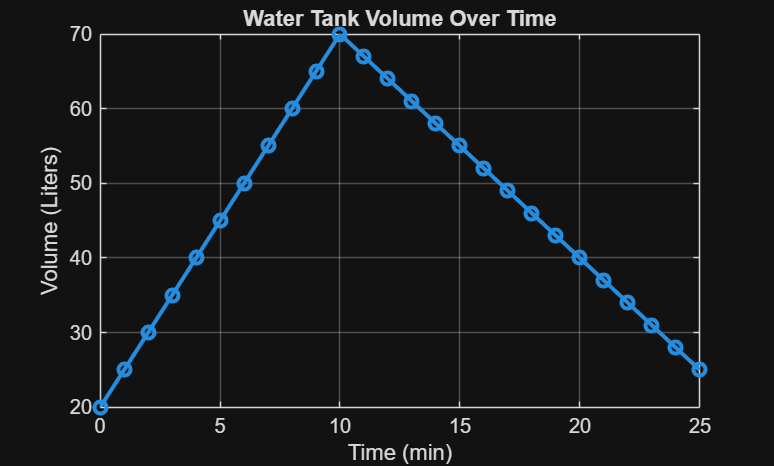

%{
Water Tank Fill-and-Drain (Piecewise Linear + Intersection)
Author: Diem-Linh Phan
Date: 4-30-2026
Purpose:
    Models volume of a tank of water over time
Input:
    - N/A:  Function is not expecting arguments.
Output:
    - Graph showing the tank volume over time 
MATLAB tools/functions:
    - functions
    - plots
%}
t = 0:1:25;
V = zeros(size(t));

% Fill (0-10 min)
mask1 = (t >= 0 & t <= 10);
V(mask1) = 5*t(mask1) + 20;

% Drain (10-25 min)
mask2 = (t > 10 & t <= 25);
V(mask2) = -3*(t(mask2) - 10) + 70;

% Plot
plot(t, V, '-o', 'LineWidth', 2)
xlabel('Time (min)'); ylabel('Volume (Liters)');
title('Water Tank Volume Over Time');
grid on;

%{
the slopes represent the rate at which the volume increased or decreased
over time.
%}